% This is a generic program to generate plots for Lab #4
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Date: August 6th, 2020
% Dr. Vibhav Durgesh
% Rev 0.0
% User has to provide appropriate information - see beginning of code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all
close all
clc

## Start of user information %% Make sure to add the data from your own experiment

volt = [0 1 2 3 4 5];
T_T_DMM = [0.000755	1.00488	1.9865	2.9974	4.0287	4.9852];
H_H_DMM = [0.001	1.006	1.988	3	4.032	4.99];
oscilloscope = [0.0032295	1.04	2.03	3.06	4.09	5.06];
ni_das = [0.0034697	1.01536458	1.98711539	2.99735815	4.02799091	4.98391173];

## End user required information

Difference in Voltage Measurements

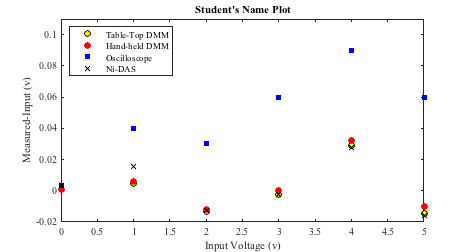

v1 = T_T_DMM - volt;
v2 = H_H_DMM - volt;
v3 = oscilloscope - volt;
v4 = ni_das - volt;

% Generating figure with specific size
figure(1)
set(gcf,'unit','inches','position',[0.50 0.50 6.50 3.50],...
        'defaultaxesfontsize',10,'defaultaxesfontname','times');
% Plotting data
plot(volt, v1,'ko','markerfacecolor','y');hold on
plot(volt, v2,'ro','markerfacecolor','r')
plot(volt, v3,'bs','markerfacecolor','b')
plot(volt, v4, 'kx')
ylim([-0.02 0.11])
xlabel('Input Voltage (v)')
ylabel('Measured-Input (v)')
legend('Table-Top DMM','Hand-held DMM','Oscilloscope','Ni-DAS','location','northwest')
title('Student''s Name Plot')

## Saving the files in png and pdf format

figName = ['../Figures/Student_Name_Exp04_Part1'];
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'PaperSize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')